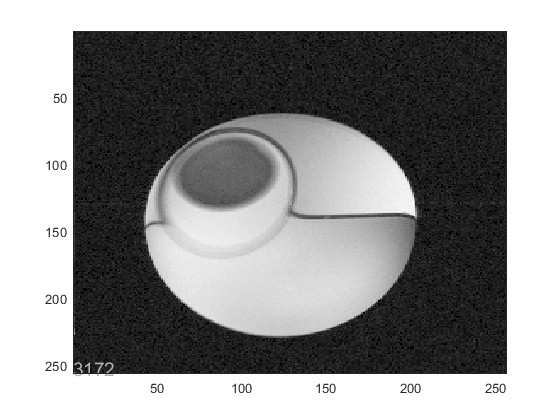

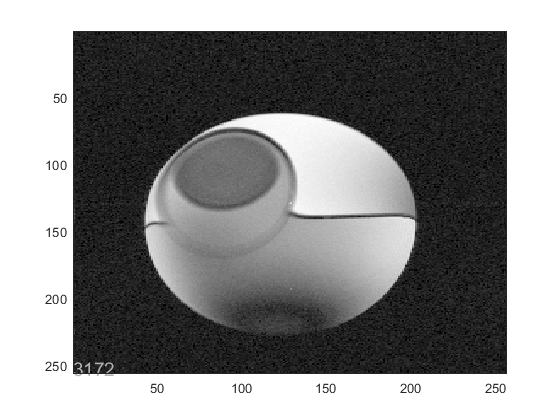

filename = '502_Dixon_0';
kspace = loadfid(filename);
kspace_real = abs(kspace);
image1 = fftshift(ifft2(fftshift(kspace)));
image1abs = abs(image1);
image1phase = atan2(imag(image1),real(image1))*180/pi;

new_complex_0 = image1;

filename = '502_Dixon_180';
kspace = loadfid(filename);
kspace_real = abs(kspace);
image1 = fftshift(ifft2(fftshift(kspace)));
image1abs = abs(image1);
image1phase = atan2(imag(image1),real(image1))*180/pi;

new_complex_180 = image1;

TwoPointWater = (new_complex_0 + new_complex_180)/2;
TwoPointFat = (new_complex_0 - new_complex_180)/2;

figure;
imagesc(abs(TwoPointWater))
watermark_image('3172')
colormap(gray)
brighten(0.5)

figure;
imagesc(abs(TwoPointFat))
watermark_image('3172')
colormap(gray)
brighten(0.5)